**Ejercicio 1**

Construir la matriz A correspondiente al sistema.

I = [-2 0 0 2
    -1/2 -4 0 -3/2
    -1 -4 -3/2 -1
    1/2 -2 -1/2 -3/2]

I =    -2.0000         0         0    2.0000
   -0.5000   -4.0000         0   -1.5000
   -1.0000   -4.0000   -1.5000   -1.0000
    0.5000   -2.0000   -0.5000   -1.5000


V = diag([2 1 4 2])

V =      2     0     0     0
     0     1     0     0
     0     0     4     0
     0     0     0     2


A = I*V

A =     -4     0     0     4
    -1    -4     0    -3
    -2    -4    -6    -2
     1    -2    -2    -3


Obtenemos los autovectores y autovalores de A

[V,L] = eig(A)

V =     0.5774   -0.2440    0.5643    0.8729
   -0.5774    0.6175   -0.2648   -0.2182
   -0.0000   -0.7470   -0.5991    0.0000
    0.5774   -0.0343   -0.5025   -0.4364


L =     0.0000         0         0         0
         0   -3.4384         0         0
         0         0   -7.5616         0
         0         0         0   -6.0000


Examinando los autovalores vemos que uno de ellos es cero y el resto son negativos. Por tanto, la evolución de ellos solo va a depender del autovector asociado a dicho autovalor cero, ya que el efecto del resto se hace cero con el tiempo. Dependiendo de la condición inicial, La empresa E1 y la E4 tendrán la misma ganacia o pérdida La empresa E2 tendrá una ganacia o perdida justo contraria a las de E1 y E4. La empresa E3, termina con el mismo valor con que terminó la sesión el ayer.

**Ejercicio 2**

Para integrar numéricamente el resultado, desde un valor inicial arbitrario de la variación de precios, Creamos una función para el sistema para luego integrarla con ode45. (Ver el final del fichero)

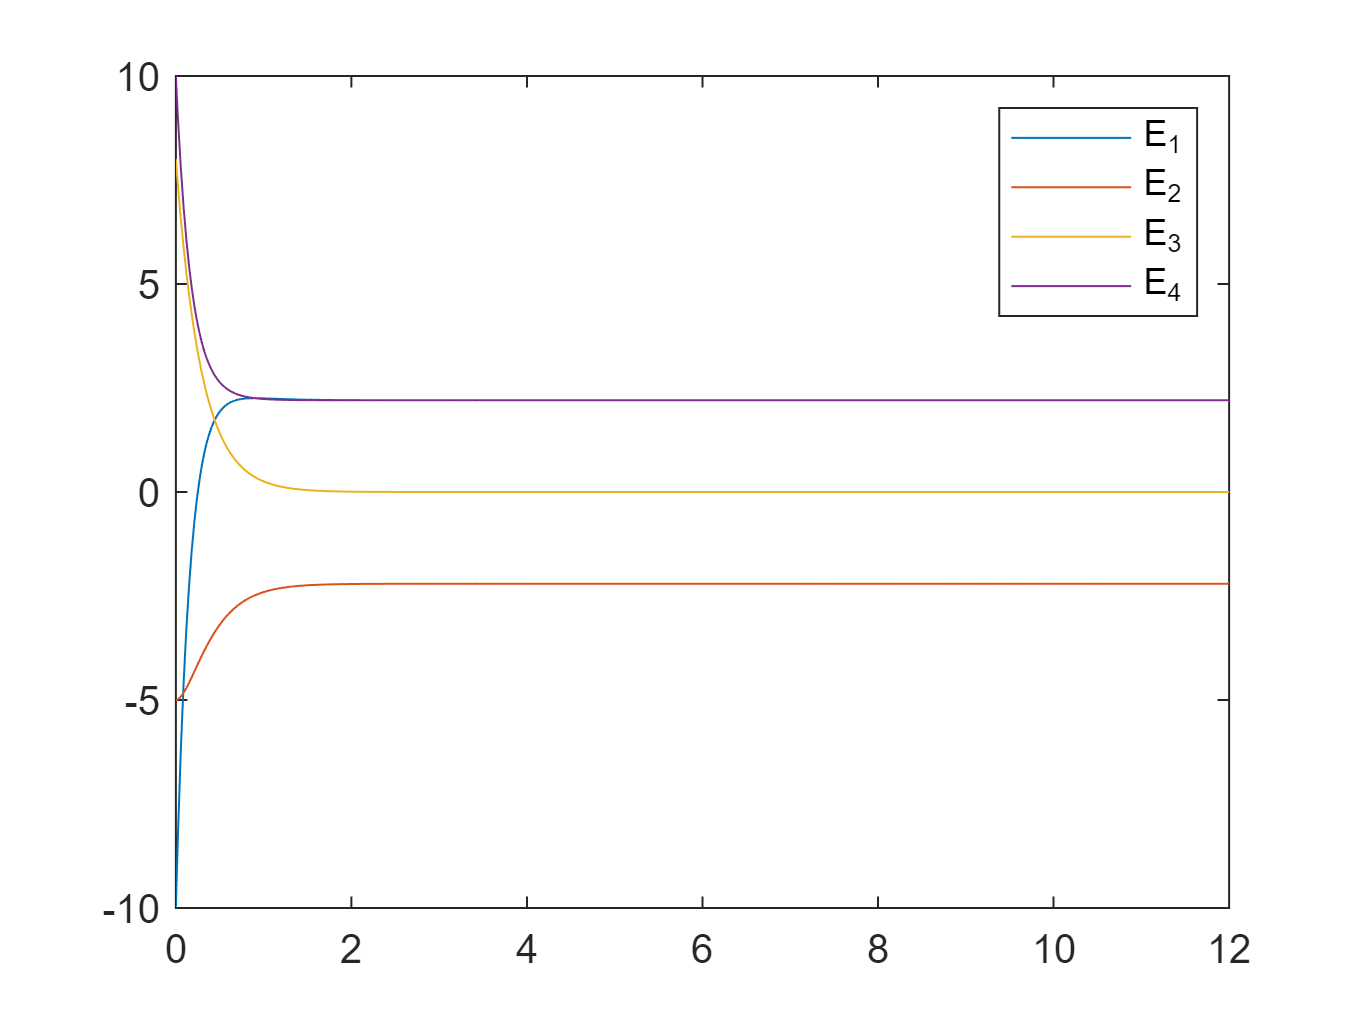

sys = @(t,x)sistema_lineal(t,x,A);
tf = 12;
x0 = [-10;-5;8;10]; %elegimos unas c iniciales en rango pedido
[t,x] = ode45(sys,[0,tf],x0);
figure(1)
plot(t,x)
legend('E_1','E_2','E_3','E_4')

Graficamente se observa lo descrito analíticamente, para estas condiciones iniciales particulares.

$E_1$y $E_4$ terminan igual, $E_3$ termina en cero y $E_2$ invierte el resultado de $E_1$y $E_4$

**Ejercicio 3**

Para comprobar la condición que nos pide, es suficiente comprobar que no existe ningún autovector de $A^T$ en el kernel de $B^T$

Calculamos los autovectores de $A^T$

[VAT,LAT] = eig(A')

VAT =     0.3946   -0.3618    0.6667   -0.3890
   -0.1435   -0.7236    0.6667   -0.7779
   -0.2870   -0.4634    0.3333    0.3037
    0.8610   -0.3618    0.0000   -0.3890


LAT =     0.0000         0         0         0
         0   -7.5616         0         0
         0         0   -6.0000         0
         0         0         0   -3.4384


Como nuestra matriz (Vector columna $B$) solo tiene un elemento distinto de cero, es fácil ver que podemos controlar los precios invirtiendo en las empresas E1, E2, ó E3. No podemos invertir SOLO en E4, ya que en ese caso, el tercer autovector estaría en el kernel de $B^T$

Podemos comprobarlo numéricamente, aunque es trivial: 

B= [0;0;0;1]

B =      0
     0
     0
     1


B'*VAT

ans =     0.8610   -0.3618    0.0000   -0.3890


Lógicamente da cero para el terce autovector

También podemos usar la matriz de controlabilidad directamente. En particular, para el caso no controlable : 

Co = ctrb(A,B)

Co =      0     4   -28   204
     0    -3    17  -109
     0    -2    22  -190
     1    -3    23  -175


Rco = rank(Co)

Rco = 3

**Ejercicio 4**

Para comprobar la observabilidad del sistema, nos basta asegurar que no hay ningún autovalor de $A$ en el kernel de $C$

Vamos a volver a obtener los autovectores de $A$  para tenerlos aquí a la vista, aunque ya los obtuvimos en el apartado 1

[V,L] = eig(A)

V =     0.5774   -0.2440    0.5643    0.8729
   -0.5774    0.6175   -0.2648   -0.2182
   -0.0000   -0.7470   -0.5991    0.0000
    0.5774   -0.0343   -0.5025   -0.4364


L =     0.0000         0         0         0
         0   -3.4384         0         0
         0         0   -7.5616         0
         0         0         0   -6.0000


Es fácil ver que no podemos emplear la empresa E3 

Así por ejemplo para E3

C = [0 0 1 0]

C =      0     0     1     0


C*V

ans =    -0.0000   -0.7470   -0.5991    0.0000


Tenemos un par de autovectores en el kernel de c

Usando la matriz de observabilidad:

Ob = obsv(A,C)

Ob =      0     0     1     0
    -2    -4    -6    -2
    22    44    40    22
  -190  -380  -284  -190


ROb = rank(Ob)

ROb = 2

**Ejercicio 5**

Si queremos que nuestro sistema sea controlable y observable con las condiciones impuestas, empleando una sola entrada y una sola salida, es preciso invertir y observar lo que pasa con la empresa E1 o con la empresa E2. 

Nos están pidiendo que empleemos el gramiano de alcanzabilidad para llevar el sistema a los valores pedidos en el tiempo deseado.

Lo primero, vamos a crear las matrices $B$ y $C$ que usaremos. Lo vamos a hacer para la empresa E1,

B = [1;0;0;0]

B =      1
     0
     0
     0


C = [1 0 0 0]

C =      1     0     0     0


Vamos a comprobar, una vez más que el sistema resultante es controlable y observable (innecesario)

Rco = rank(ctrb(A,B))

Rco = 4

Ros = rank(obsv(A,C))

Ros = 4

Necesitamos obtener el valor del gramiano de alcanzabilidad

$WR[t_1,0] = \int_0^{t1} e^{At}BB^Te^{A^Tt}dt$,

Definimos una función en matlab que calcule el integrando $ e^{At}BB^Te^{A^Tt}$para cualquier valor de t (ver la función al final de este script) e integrarla numericamente.

tf = 6; %media sesion 6h
f=@(t)dgramr(t,tf,A,B); %handle a la funcion que define el integrando
wr6_0 = integral(f,0,tf,'ArrayValued',1)

wr6_0 =     0.5867   -0.4627   -0.0328    0.4717
   -0.4627    0.4393    0.0137   -0.4448
   -0.0328    0.0137    0.0070   -0.0156
    0.4717   -0.4448   -0.0156    0.4509


Definimos la variación final del precio de las acciones

xf = [10;-10;-10;-10];

Podemos ahora calcular el valor $\eta_1 = WR[0,t_f]^{-1}x_f$

eta1 = inv(wr6_0)*xf

eta1 = 	1.0e+05 *

   -0.1070
   -3.3881
   -1.1548
   -3.2705


Necesitamos crear una función $u(t)=B^T\Phi(0,t_1)^T\eta_1=B^Te^{A^T(t_1-t)} \eta_1$ para llevar nuestro sistema al valor pedido, así que la creamos (al final del fichero)

Así que creamos una función para $u(t)$ (Ver al final del archivo)

Creamos una nueva función sistema_lineal_2 (ver final)para obtener la respuesta del sistema

u = @(t)U(t,tf,A,B,eta1) %handel a la función que genera u

u = function_handle with value:
    @(t)U(t,tf,A,B,eta1)


sys = @(t,x)sistema_lineal2(t,x,u,A,B)

sys = function_handle with value:
    @(t,x)sistema_lineal2(t,x,u,A,B)


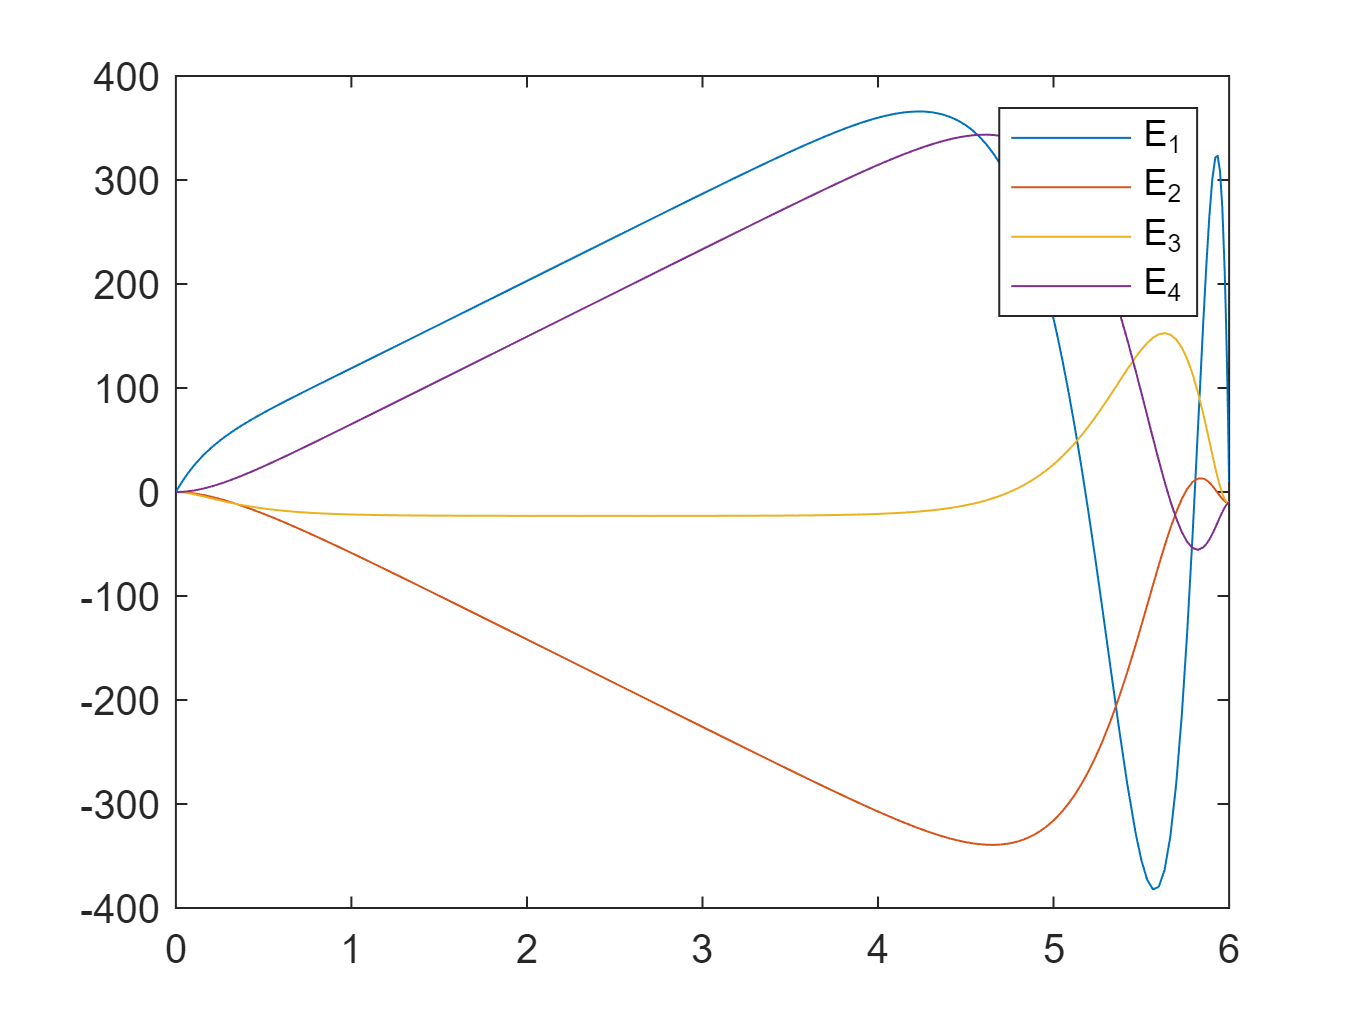

[t,x] = ode45(sys,[0,tf],[0;0;0;0]);
figure(2)
plot(t,x)
legend('E_1','E_2','E_3','E_4')

x_final = x(end,:)

x_final =    10.0025   -9.9999   -9.9953   -9.9991


Se han alcanzado los valores deseados (salvo errores numéricos en la integral)

**Ejercicio 6**

Sabemos que el sistema es controlable, Podemos poner al controlador unos polos 

K = place(A,B,[-1,-2,-3,-4])

K =    -7.0000  -19.3636  -13.2273  -11.8182


Ponemos los polos del observador 

L = place(A',C',[-5,-6,-7,-8])'

L =     9.0000
   -6.2500
   -5.5000
   10.5000


Construimos el sistema ampliado,


$$\pmatrix{\dot{x} \cr \dot{\hat{x}}} = \pmatrix{A & -BK\cr LC & A-BK - LC }\pmatrix{x \cr \hat{x}}$$


Amp = [A -B*K; L*C  A-B*K-L*C]

Amp =    -4.0000         0         0    4.0000    7.0000   19.3636   13.2273   11.8182
   -1.0000   -4.0000         0   -3.0000         0         0         0         0
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0
    9.0000         0         0         0   -6.0000   19.3636   13.2273   15.8182
   -6.2500         0         0         0    5.2500   -4.0000         0   -3.0000
   -5.5000         0         0         0    3.5000   -4.0000   -6.0000   -2.0000
   10.5000         0         0         0   -9.5000   -2.0000   -2.0000   -3.0000


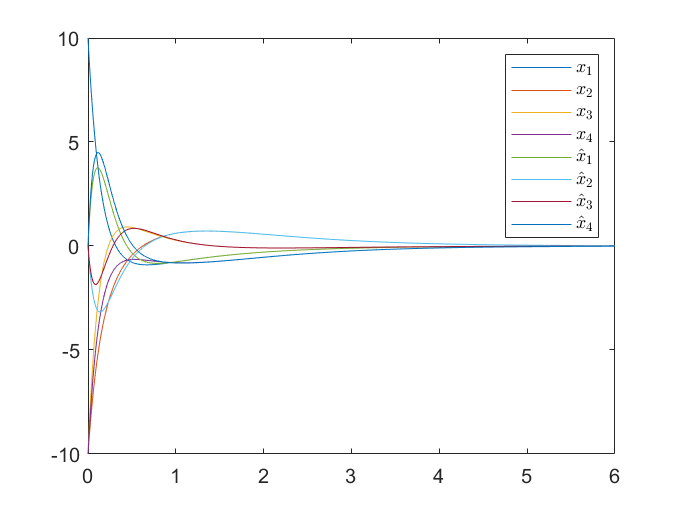

sys = @(t,x)sistema_lineal(t,x,Amp);
tf = 6;
x0 = [10;-10;-10;-10;0;0;0;0]; %c iniciales, pongo a cero las del estimador
[t,x] = ode45(sys,[0,tf],x0);
figure(3)
plot(t,x)
legend('$x_1$','$x_2$','$x_3$','$x_4$','$\hat{x}_1$','$\hat{x}_2$',...
    '$\hat{x}_3$','$\hat{x}_4$','Interpreter','latex')

Efectivamente se estabiliza en 6 horas

**Ejercicio 7**

Añadimos control integral, para ello, debemos construir la matriz ampliada

Debemos construir una matriz ampliada para incluir el error entre la salida y el valor deseado en el sistema,

$A_{mp} =\pmatrix{A & 0 \cr C & 0}$,$B_{mp} =\pmatrix{B \cr 0}$

Comprobar que el sistema ampliado es controlable y definir unos nuevos polos,

Ampi = [A zeros(4,1);C 0]

Ampi =     -4     0     0     4     0
    -1    -4     0    -3     0
    -2    -4    -6    -2     0
     1    -2    -2    -3     0
     1     0     0     0     0


Bmpi = [B;0]

Bmpi =      1
     0
     0
     0
     0


rank(ctrb(Ampi,Bmpi))

ans = 5

Colocamos los polos, añadiendo uno para la acción integral

Kt = place(Ampi,Bmpi,[-1,-2,-3,-4,-5]) %el último es para la acción integral

Kt =    -2.0000   -7.7727   -5.3864   -2.2727    2.7273


Construimos una matriz ampliada que incluya tanto el observador como el error. Recordad que por el principio de separacion no hace falta volver a comprobar la controlabilidad de la nueva matriz ampliada:

$\pmatrix{\dot{x}\cr \dot{\hat{x}}\cr \dot{e}}A_{mpo} =\pmatrix{A & -BK &-BK_i\cr LC& A-BK-LC\ & -BK_i &\cr C &0 &0}\pmatrix{x\cr \hat{x}\cr e}+ \pmatrix{0\cr 0\cr -yd} $,

Donde, lógicamente también pasamos el error integral al estimador

 Ampo = [A  -B*Kt(1:4) -B*Kt(5)
         L*C A-B*Kt(1:4)-L*C -B*Kt(5)
         C zeros(1,4) 0]

Ampo =    -4.0000         0         0    4.0000    2.0000    7.7727    5.3864    2.2727   -2.7273
   -1.0000   -4.0000         0   -3.0000         0         0         0         0         0
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0         0
    9.0000         0         0         0  -11.0000    7.7727    5.3864    6.2727   -2.7273
   -6.2500         0         0         0    5.2500   -4.0000         0   -3.0000         0
   -5.5000         0         0         0    3.5000   -4.0000   -6.0000   -2.0000         0
   10.5000         0         0         0   -9.5000   -2.0000   -2.0000   -3.0000         0
    1.0000         0         0         0         0         0         0         0         0


Para la entrada, creamos un vector B, de tamaño adecuado para introducir la referencia

     Bmpo = [zeros(size(Ampo,1)-1,1);1]

Bmpo =      0
     0
     0
     0
     0
     0
     0
     0
     1


Por último integramos el sistema ampliado empleando como entrada el valor final al que queremos que llegue nuestra empresa

u = @(t)-15 %lo hago así para reutilizar sistema_lineal_2

u = function_handle with value:
    @(t)-15


x0 = [10;-10;-10;-10;0;0;0;0;0]

x0 =     10
   -10
   -10
   -10
     0
     0
     0
     0
     0


sys = @(t,x)sistema_lineal2(t,x,u,Ampo,Bmpo)

sys = function_handle with value:
    @(t,x)sistema_lineal2(t,x,u,Ampo,Bmpo)


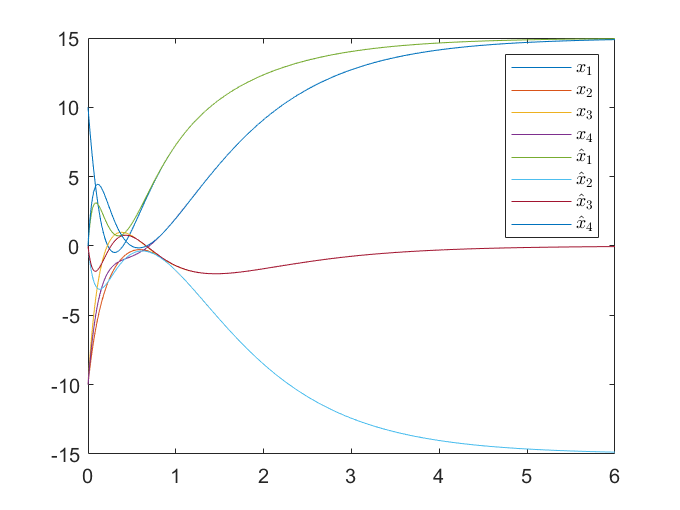

[t,x] = ode45(sys,[0,tf],x0);
figure(4)
plot(t,x(:,1:8))
legend('$x_1$','$x_2$','$x_3$','$x_4$','$\hat{x}_1$','$\hat{x}_2$',...
    '$\hat{x}_3$','$\hat{x}_4$','Interpreter','latex')

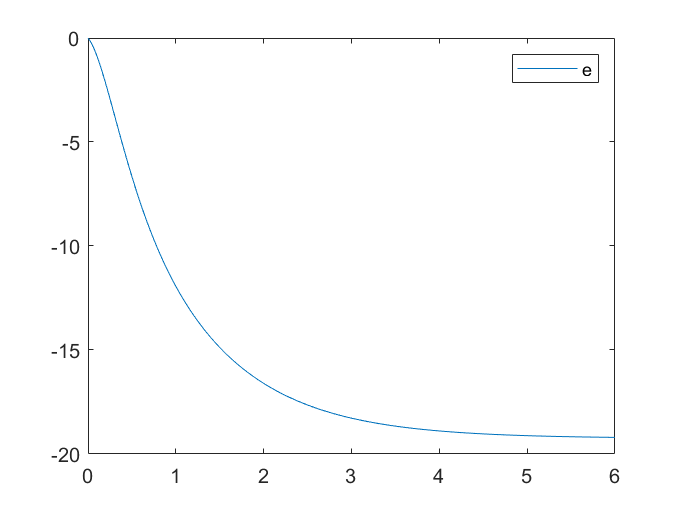

figure(5)
plot(t,x(:,9))
legend('e')

Vemos que la empresas E1 y E4 llegan al valor 15, E3 no gana ni pierde y E2 Se hunde a -15. Asi qu es de esperar que esto calme los ánimos de todo el mundo menos de E2

Repetimos el cálculo para la empresa E2, vamos a crear las matrices $B$ y $C$ que usaremos. Lo vamos a hacer para la empresa E1,

B = [0;1;0;0]

B =      0
     1
     0
     0


C = [0 1 0 0]

C =      0     1     0     0


Vamos a comprobar, una vez más que el sistema resultante es controlable y observable

Rco = rank(ctrb(A,B))

Rco = 4

Ros = rank(obsv(A,C))

Ros = 4

Necesitamos obtener el valor del gramiano de alacnzabilidad

$WR[t_1,0] = \int_0^{t1} e^{At}BB^Te^{A^Tt}dt$,

Definimos una función en matlab que calcule el integrando $ e^{At}BB^Te^{A^Tt}$para cualquier valor de t (ver la función al final de este script) e integrarla numericamente.

tf = 6; %media sesion 6h
f=@(t)dgramr(t,tf,A,B); %handle a la funcion que define el integrando
wr6_0 = integral(f,0,tf,'ArrayValued',1)

wr6_0 =     0.0626   -0.0760    0.0128    0.0639
   -0.0760    0.2109   -0.0581   -0.0910
    0.0128   -0.0581    0.0280    0.0194
    0.0639   -0.0910    0.0194    0.0673


Definimos la variación final del precio de las acciones

xf = [-10;10;-10;-10];

Podemos ahora calcular el valor $\eta_1 = WR[0,t_f]^{-1}x_f$

eta1 = inv(wr6_0)*xf

eta1 = 	1.0e+03 *

   -4.4819
   -0.0553
   -1.5160
    4.4720


Necesitamos crear una función $u(t)=B^T\Phi(0,t_1)^T\eta_1=B^Te^{A^T(t_1-t)} \eta_1$ para llevar nuestro sistema al valor pedido, así que la creamos (al final del fichero)

Así que creamos una función para $u(t)$ (Ver al final del archivo)

Creamos una nueva función sistema_lineal_2 (ver final)para obtener la respuesta del sistema

u = @(t)U(t,tf,A,B,eta1) %handel a la función que genera u

u = function_handle with value:
    @(t)U(t,tf,A,B,eta1)


sys = @(t,x)sistema_lineal2(t,x,u,A,B)

sys = function_handle with value:
    @(t,x)sistema_lineal2(t,x,u,A,B)


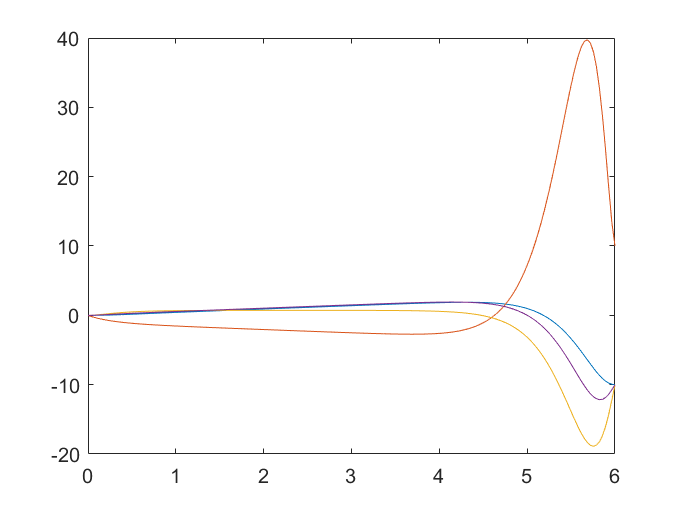

[t,x] = ode45(sys,[0,tf],[0;0;0;0]);
figure(2)
plot(t,x)

X_final = x(end,:)

X_final =   -10.0004   10.0016   -9.9971   -9.9986


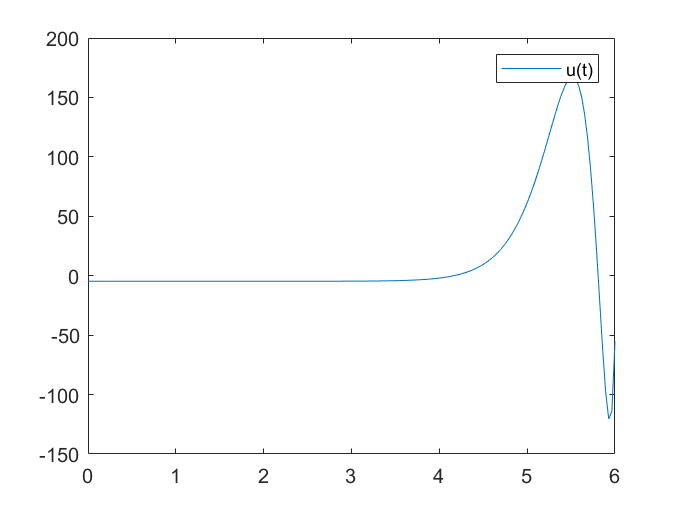

u_minE = zeros(size(t));
for i =1:length(t)
    u_minE(i)=u(t(i));
end
figure(3)
plot(t,u_minE)
legend('u(t)')

Sabemos que el sistema es controlable, Podemos poner al controlador unos polos.

K = place(A,B,[-1,-2,-3,-4])

K =    -1.5000   -7.0000   -5.0000   -7.0000


Ponemos los polos del observador

L = place(A',C',[-5,-6,-7,-8])'

L =   -10.1053
    9.0000
    2.2105
  -10.6316


Construimos el sistema ampliado,


$$\pmatrix{\dot{x} \cr \dot{\hat{x}}} = \pmatrix{A & -BK\cr LC & A-BK - LC }\pmatrix{x \cr \hat{x}}$$


Amp = [A -B*K; L*C  A-B*K-L*C]

Amp =    -4.0000         0         0    4.0000         0         0         0         0
   -1.0000   -4.0000         0   -3.0000    1.5000    7.0000    5.0000    7.0000
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0
         0  -10.1053         0         0   -4.0000   10.1053         0    4.0000
         0    9.0000         0         0    0.5000   -6.0000    5.0000    4.0000
         0    2.2105         0         0   -2.0000   -6.2105   -6.0000   -2.0000
         0  -10.6316         0         0    1.0000    8.6316   -2.0000   -3.0000


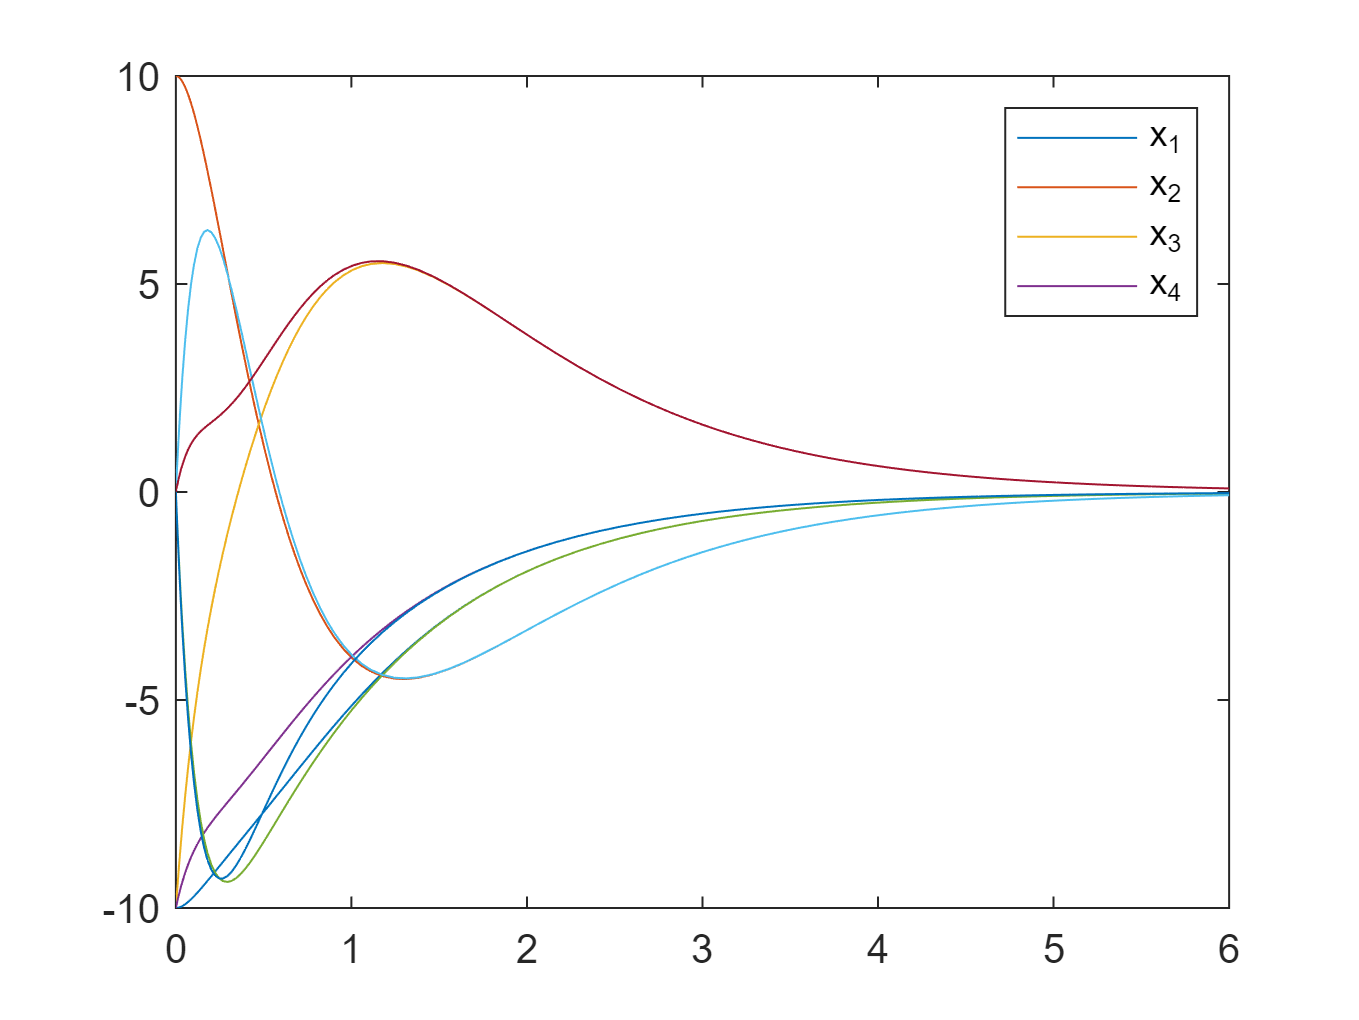

sys = @(t,x)sistema_lineal(t,x,Amp);
tf = 6;
x0 = [-10;10;-10;-10;0;0;0;0]; %c iniciales, pongo a cero las del estimador
[t,x] = ode45(sys,[0,tf],x0);
figure(3)
plot(t,x)
legend('x_1','x_2','x_3','x_4')

Efectivamente se estabiliza en 6 horas (esto no se pide)

Añadimos control integral, para ello, debemos construir la matriz ampliada

Debemos construir una matriz ampliada para incluir el error entre la salida y el valor deseado en el sistema,

$A_{mp} =\pmatrix{A & 0 \cr C & 0}$,$B_{mp} =\pmatrix{B \cr 0}$

Comprobar que el sistema ampliado es controlable y definir unos nuevos polos,

Ampi = [A zeros(4,1);C 0]

Ampi =     -4     0     0     4     0
    -1    -4     0    -3     0
    -2    -4    -6    -2     0
     1    -2    -2    -3     0
     0     1     0     0     0


Bmpi = [B;0]

Bmpi =      0
     1
     0
     0
     0


rank(ctrb(Ampi,Bmpi))

ans = 5

Colocamos los polos, añadiendo uno para la acción integral

Kt = place(Ampi,Bmpi,[-1,-2,-3,-4,-5]) %el último es para la acción integral

Kt =     0.6875   -2.0000   -3.7500    1.7500    7.5000


Construimos una matriz ampliada que incluya tanto el observador como el error. Recordad que por el principio de separacion no hace falta volver a comprobar la controlabilidad de la nueva matriz ampliada:

$\pmatrix{\dot{x}\cr \dot{\hat{x}}\cr \dot{e}}A_{mpo} =\pmatrix{A & -BK &-BK_i\cr LC& A-BK-LC\ & -BK_i &\cr C &0 &0}\pmatrix{x\cr \hat{x}\cr e}+ \pmatrix{0\cr 0\cr -yd} $,

Donde, lógicamente también pasamos el error integral al estimador

 Ampo = [A  -B*Kt(1:4) -B*Kt(5)
         L*C A-B*Kt(1:4)-L*C -B*Kt(5)
         C zeros(1,4) 0]

Ampo =    -4.0000         0         0    4.0000         0         0         0         0         0
   -1.0000   -4.0000         0   -3.0000   -0.6875    2.0000    3.7500   -1.7500   -7.5000
   -2.0000   -4.0000   -6.0000   -2.0000         0         0         0         0         0
    1.0000   -2.0000   -2.0000   -3.0000         0         0         0         0         0
         0  -10.1053         0         0   -4.0000   10.1053         0    4.0000         0
         0    9.0000         0         0   -1.6875  -11.0000    3.7500   -4.7500   -7.5000
         0    2.2105         0         0   -2.0000   -6.2105   -6.0000   -2.0000         0
         0  -10.6316         0         0    1.0000    8.6316   -2.0000   -3.0000         0
         0    1.0000         0         0         0         0         0         0         0


Para la entrada, creamos un vector B, de tamaño adecuado para introducir la referencia

     Bmpo = [zeros(size(Ampo,1)-1,1);1]

Bmpo =      0
     0
     0
     0
     0
     0
     0
     0
     1


Por último integramos el sistema ampliado empleando como entrada el valor final al que queremos que llegue nuestra empresa

u = @(t)-15 %lo hago así para reutilizar sistema_lineal_2

u = function_handle with value:
    @(t)-15


x0 = [-10;10;-10;-10;0;0;0;0;0]

x0 =    -10
    10
   -10
   -10
     0
     0
     0
     0
     0


sys = @(t,x)sistema_lineal2(t,x,u,Ampo,Bmpo)

sys = function_handle with value:
    @(t,x)sistema_lineal2(t,x,u,Ampo,Bmpo)


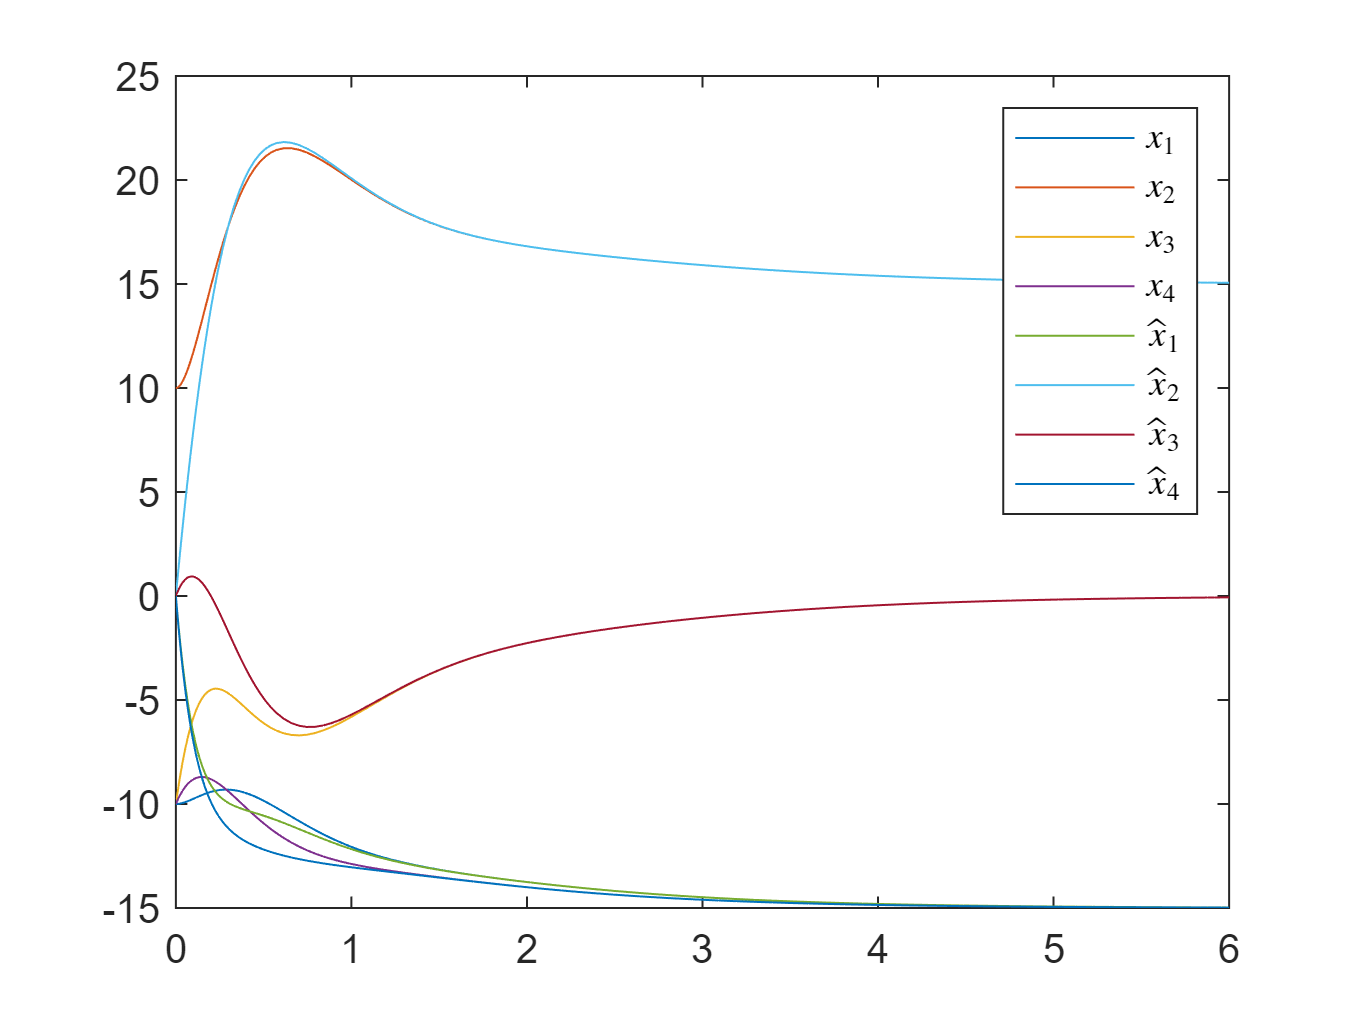

[t,x] = ode45(sys,[0,tf],x0);
figure(4)
plot(t,x(:,1:8))
legend('$x_1$','$x_2$','$x_3$','$x_4$','$\hat{x}_1$','$\hat{x}_2$',...
    '$\hat{x}_3$','$\hat{x}_4$','Interpreter','latex')

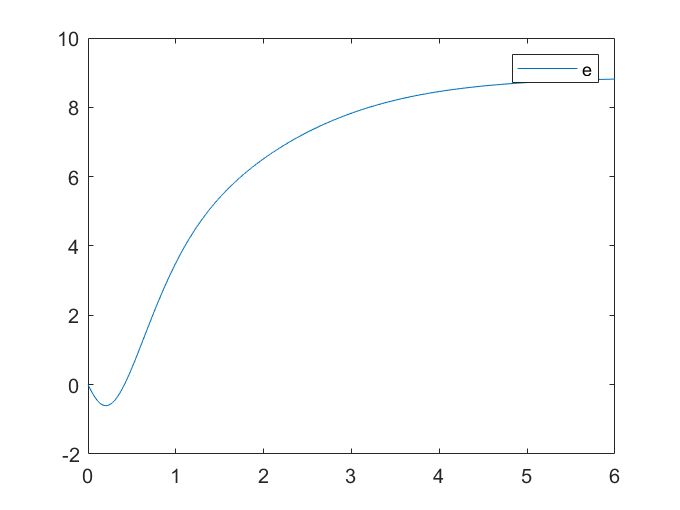

figure(5)
plot(t,x(:,9))
legend('e')

En este caso hemos hundido a la competencia (eso sí, suavemente)

function xdot = sistema_lineal(t,x,A)
%Modelo lineal elemental para estudiar la evolucion
%desde un valor inicial
xdot = A*x;
end

function  dwr= dgramr(t,t1,A,B)
%esta función permite construir el valor del integrando del grammiano de
%alcanzabilidad para un par A,B y un tiempo final t1,tiempo inicial t0=0
%si creamos un handle f = @(t)gramr(t,t1,A,B) in lo pasamos a la funcion de
%matlab integral, obtenemos el valor de gramiano Wr(t1,0)
dwr = expm(A*(t1-t))*B*B'*expm(A'*(t1-t));
end
function s = U(t,t1,A,B,eta)
%función para obtener la entrada de control de mínima energía que lleva un
%sistema LTI de x0 = 0 a X1. eta, de debe obtenerse a partir de x1 calculando
%e invirtiendo el gramiano de alcanzabilidad
s = B'*expm(A'*(t1-t))*eta;
end
function xdot = sistema_lineal2(t,x,u,A,B)
xdot = A*x+B*u(t);
end